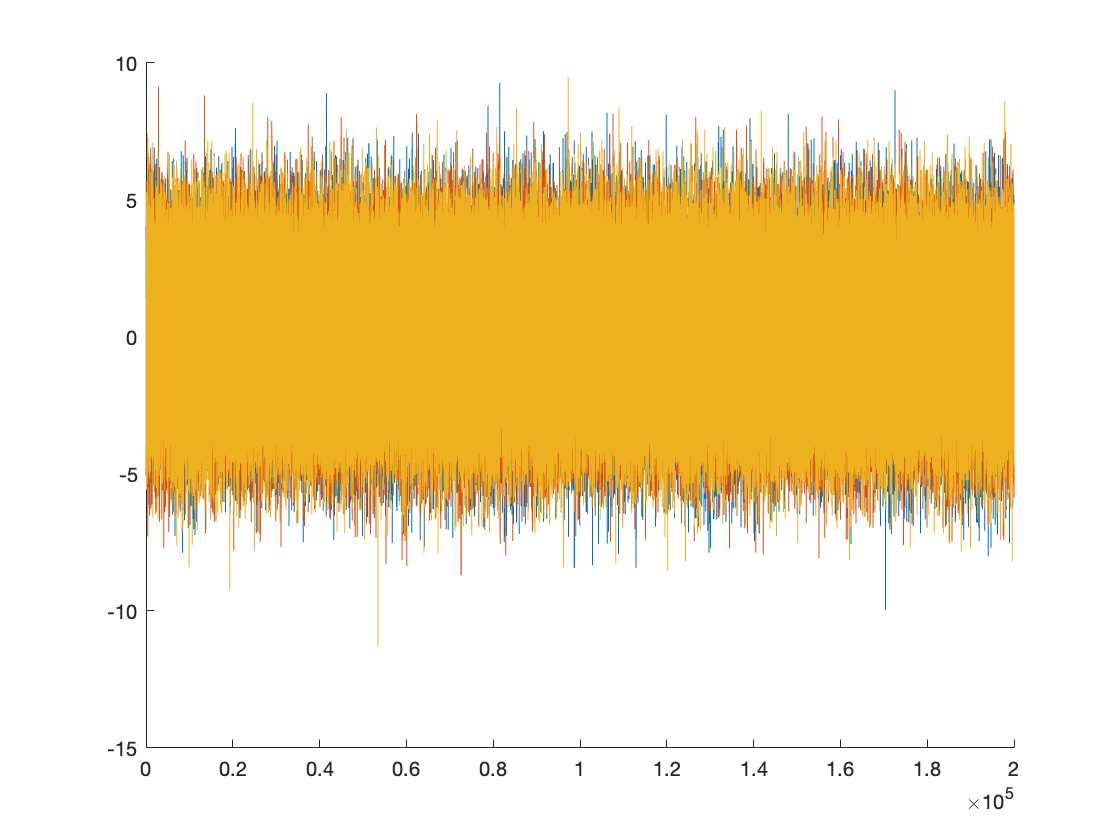


rng(1)
noise_wn1 = generate_white_noise(200000, 2);

rng(2)
noise_wn2 = generate_white_noise(200000, 2);

rng(3)
noise_wn3 = generate_white_noise(200000, 2);

figure
hold on
plot(noise_wn1)
plot(noise_wn2)
plot(noise_wn3)

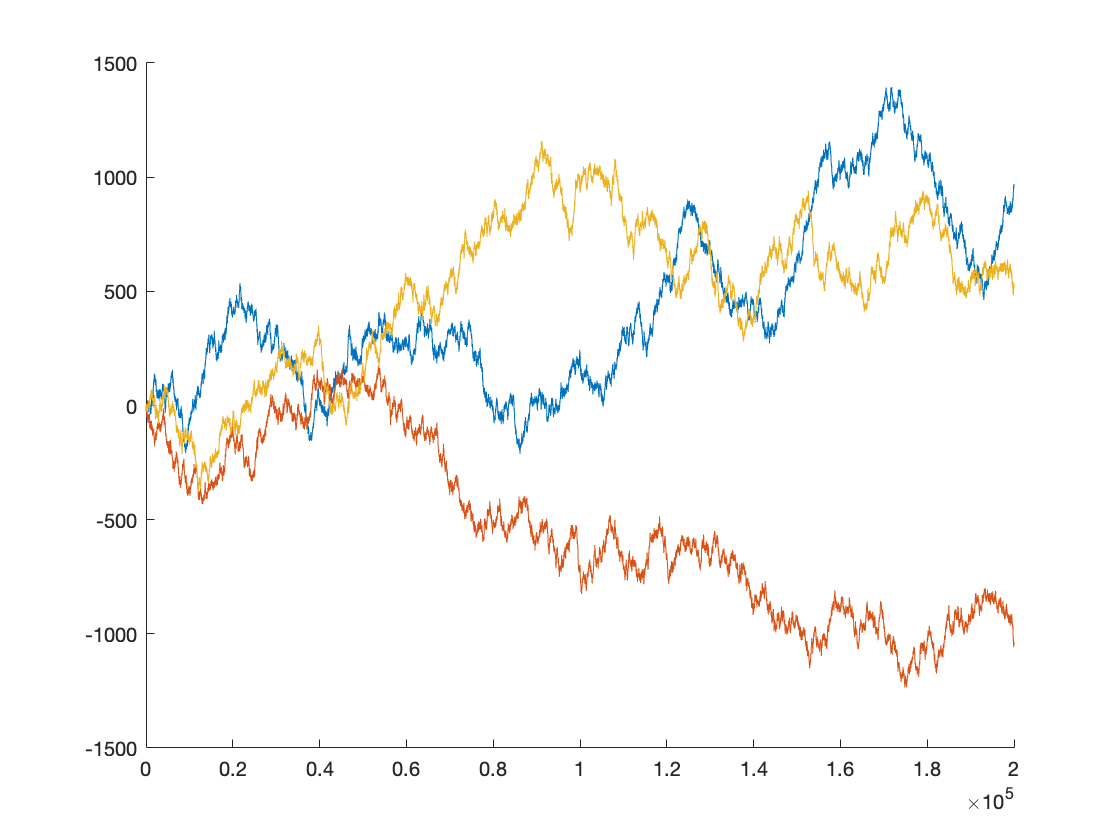


rng(1)
noise_rw1 = generate_random_walk(200000, 2);

rng(2)
noise_rw2 = generate_random_walk(200000, 2);

rng(3)
noise_rw3 = generate_random_walk(200000, 2);

figure
hold on
plot(noise_rw1)
plot(noise_rw2)
plot(noise_rw3)

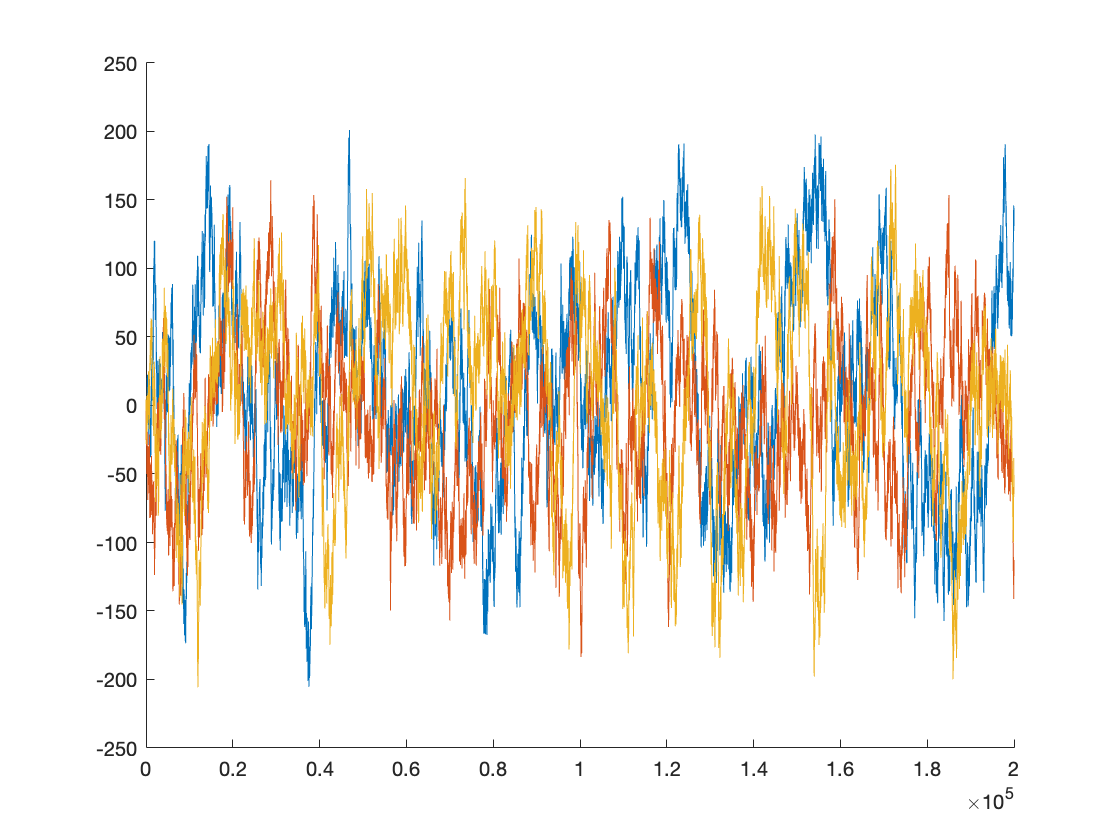

rng(1)
noise_gm11 = generate_gauss_markov(200000, 2, 1/2000);

rng(2)
noise_gm12 = generate_gauss_markov(200000, 2, 1/2000);

rng(3)
noise_gm13 = generate_gauss_markov(200000, 2, 1/2000);

figure
hold on
plot(noise_gm11)
plot(noise_gm12)
plot(noise_gm13)

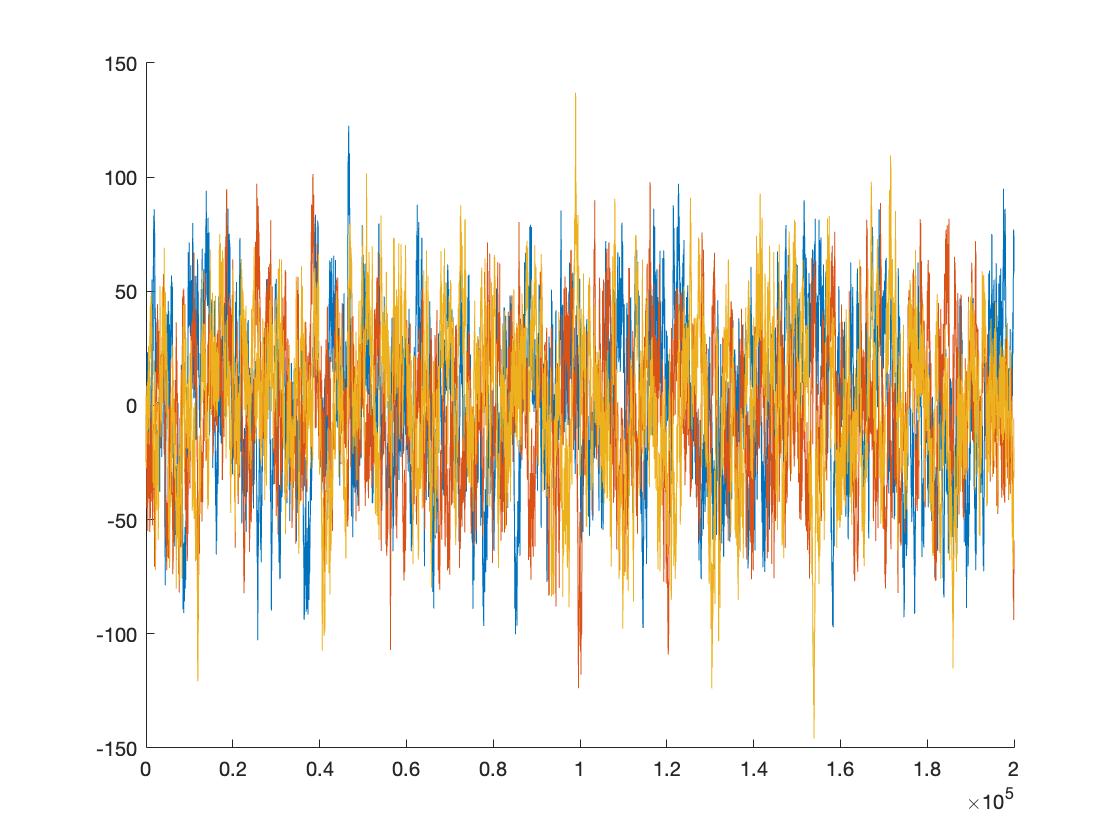

rng(1)
noise_gm21 = generate_gauss_markov(200000, 2, 1/500);

rng(2)
noise_gm22 = generate_gauss_markov(200000, 2, 1/500);

rng(3)
noise_gm23 = generate_gauss_markov(200000, 2, 1/500);

figure
hold on
plot(noise_gm21)
plot(noise_gm22)
plot(noise_gm23)


save('noises.mat')

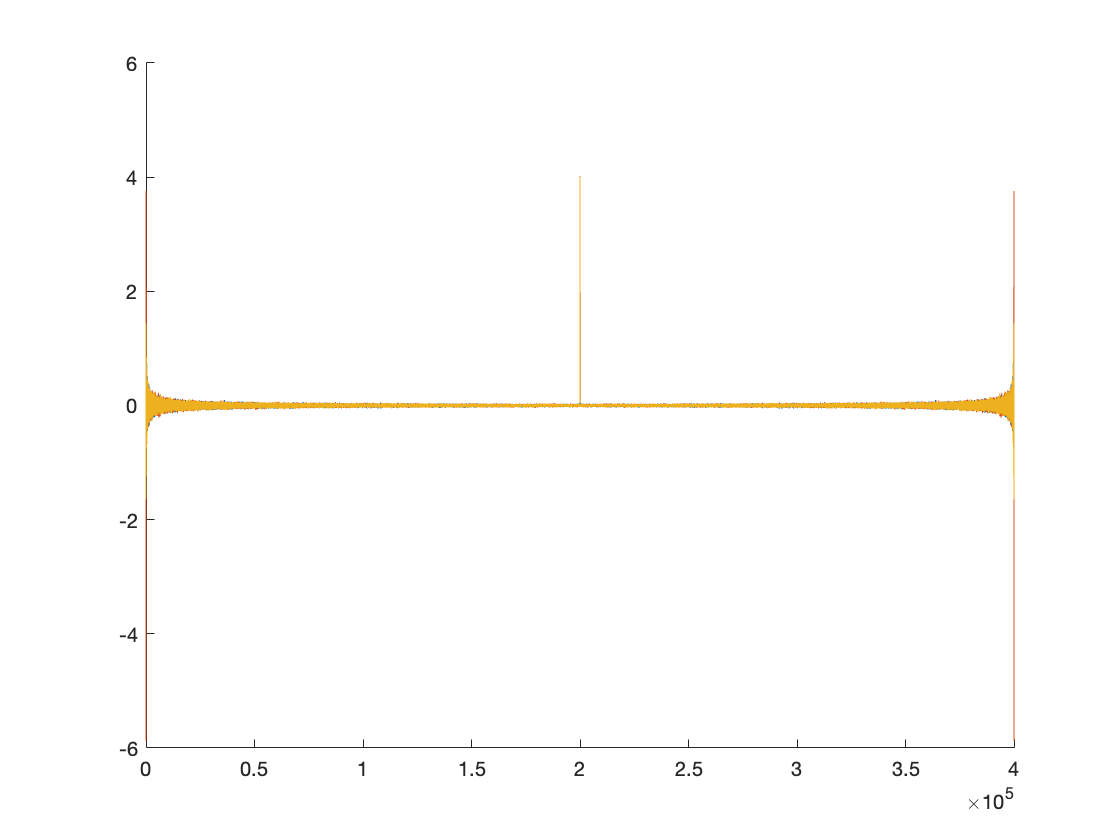

corr_wn1 = xcorr(noise_wn1, 'unbiased');
corr_wn2 = xcorr(noise_wn2, 'unbiased');
corr_wn3 = xcorr(noise_wn3, 'unbiased');

figure
hold on
plot(corr_wn1)
plot(corr_wn2)
plot(corr_wn3)

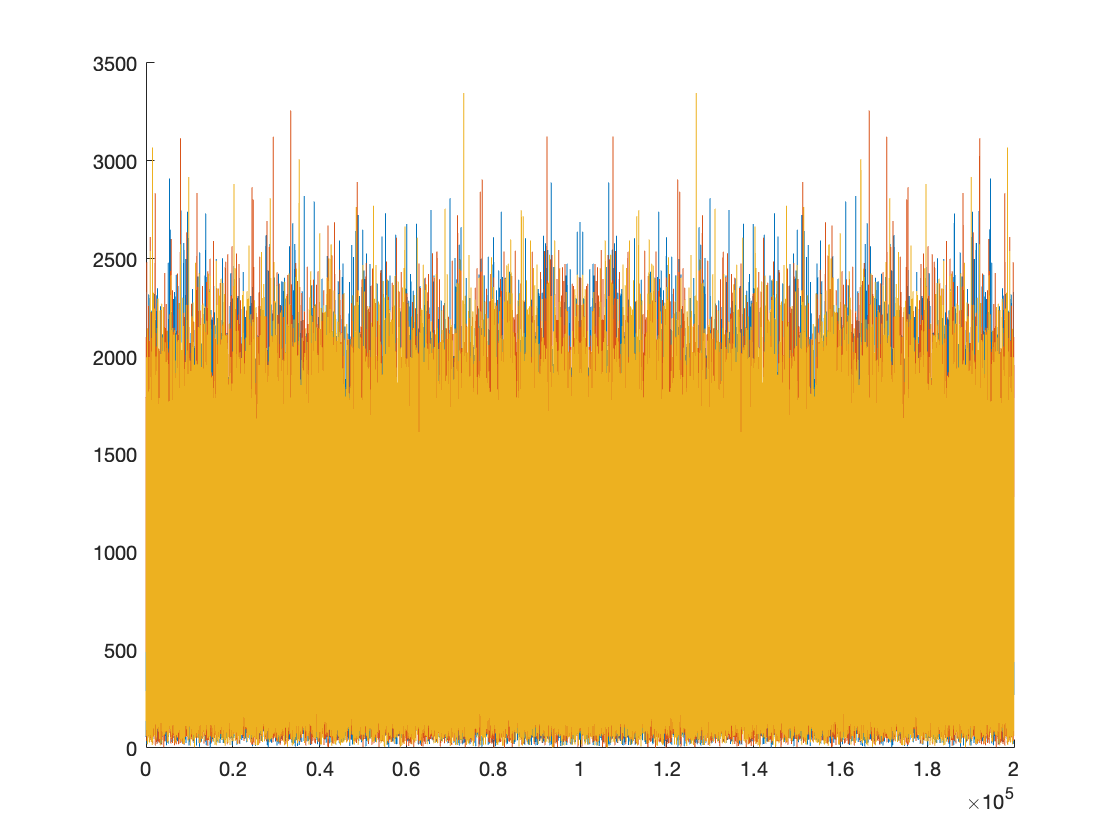


figure
hold on
plot(abs(fftshift(fft(noise_wn1))))
plot(abs(fftshift(fft(noise_wn2))))
plot(abs(fftshift(fft(noise_wn3))))

corr_wn1 = xcorr(noise_wn1, 'unbiased');
corr_wn2 = xcorr(noise_wn2, 'unbiased');
corr_wn3 = xcorr(noise_wn3, 'unbiased');

figure
hold on
plot(corr_wn1)
plot(corr_wn2)
plot(corr_wn3)

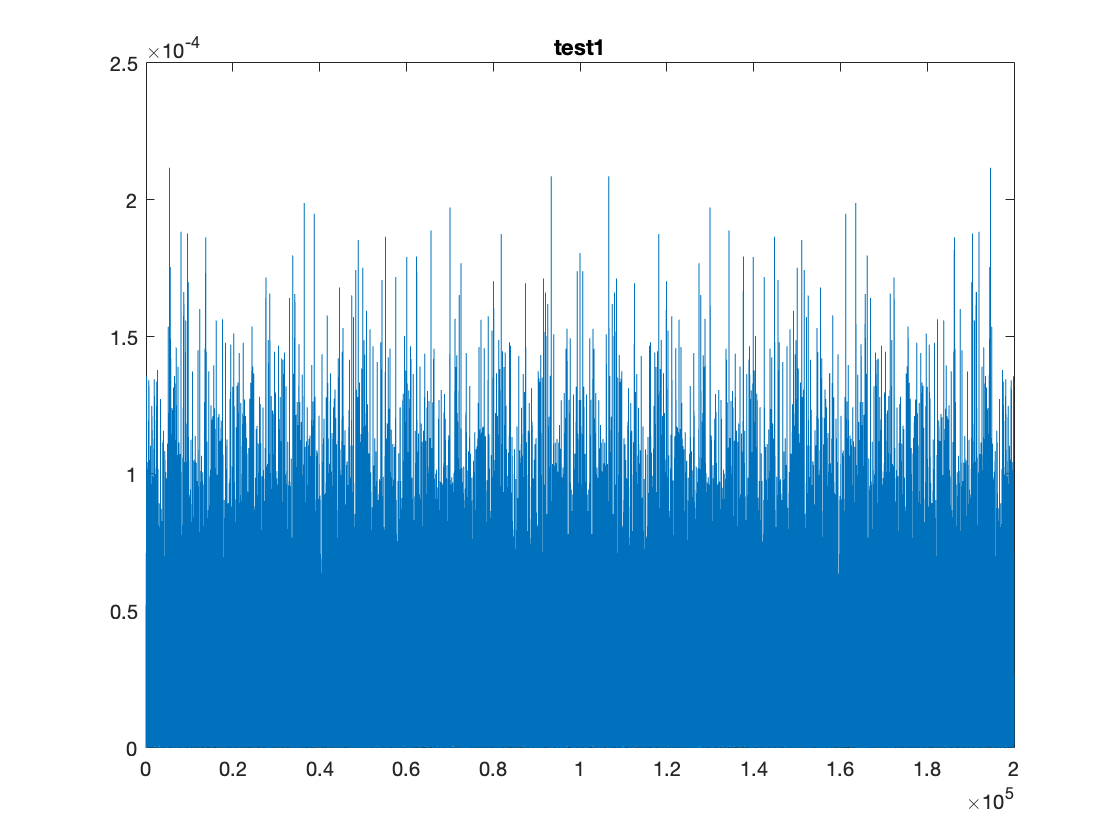


figure
plot(abs(fftshift(fft(noise_wn1 / length(noise_wn1)).^2)))
title("test1")

sum(abs(fftshift(fft(noise_wn1 / length(noise_wn1)).^2)))

ans = 4.0225


figure
plot(abs(pwelch(noise_wn1, [], [], length(noise_wn1), length(noise_wn1), 'centered')))

sum(noise_wn1.*noise_wn1/length(noise_wn1))

ans = 4.0225

sum(abs(pwelch(noise_wn1, [], [], length(noise_wn1), length(noise_wn1), 'centered')))

ans = 4.0232

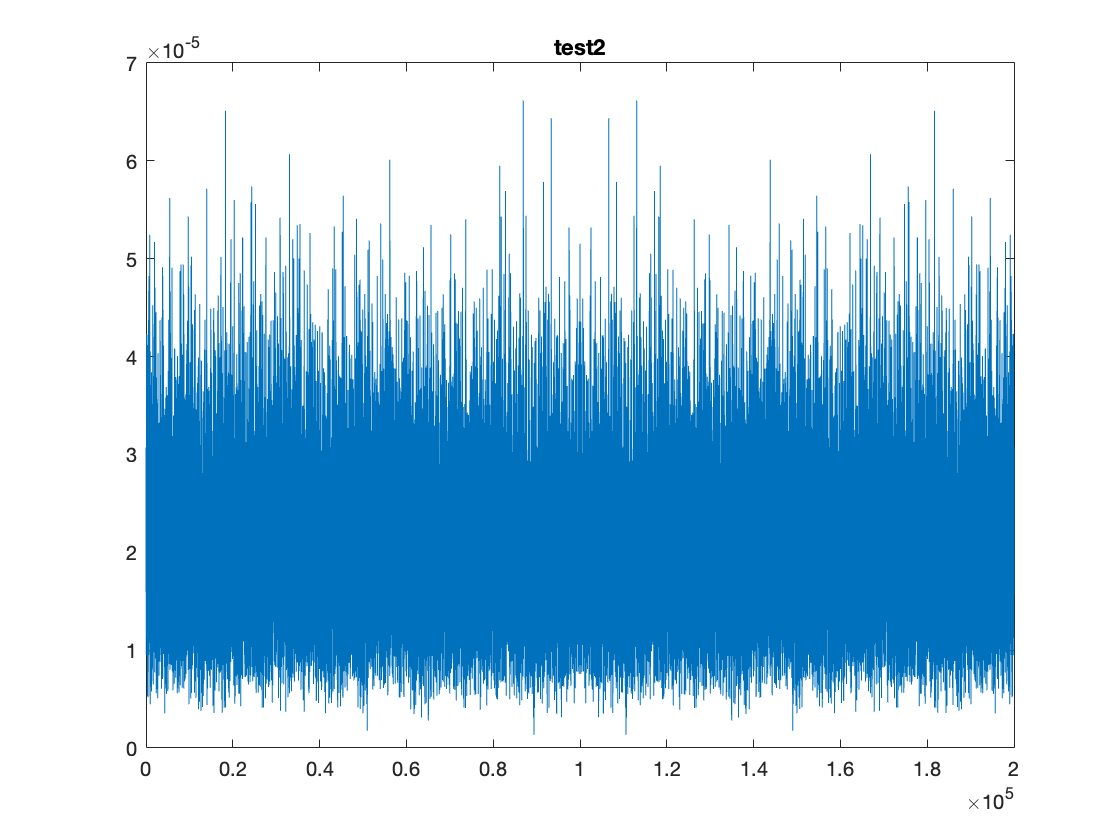

title("test2")

%plot(abs(fftshift(fft(noise_rw3))))

corr_wn1 = xcorr(noise_wn1, 'unbiased');
corr_wn2 = xcorr(noise_wn2, 'unbiased');
corr_wn3 = xcorr(noise_wn3, 'unbiased');

figure
hold on
plot(corr_wn1)
plot(corr_wn2)
plot(corr_wn3)

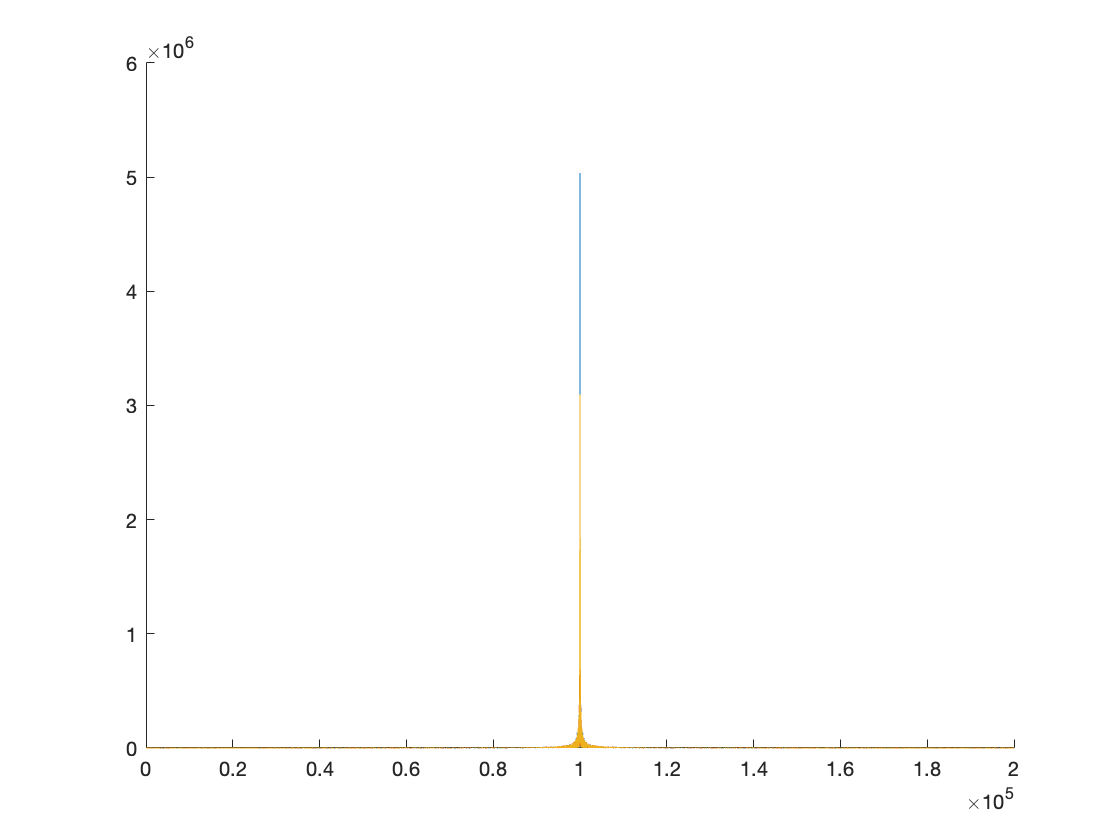


figure
hold on
plot(abs(fftshift(fft(noise_gm11))))
plot(abs(fftshift(fft(noise_gm12))))
plot(abs(fftshift(fft(noise_gm13))))

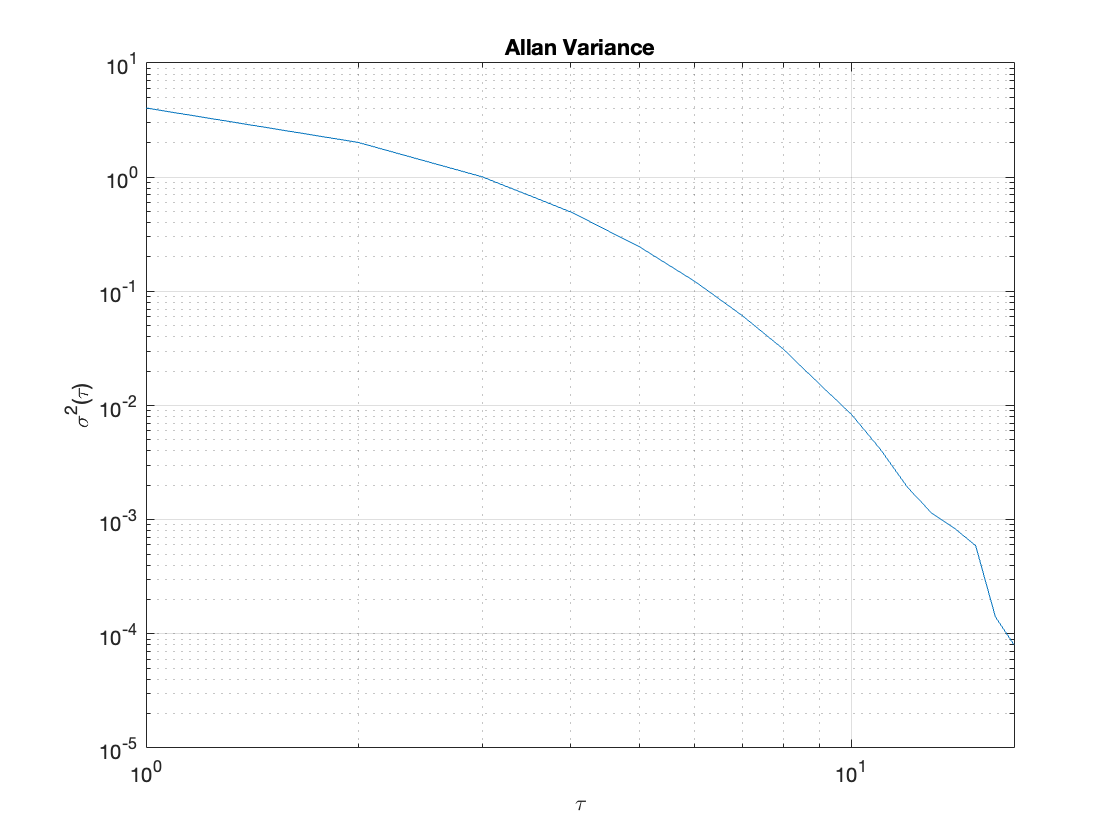



figure
loglog(allanvar(noise_wn1))
xlabel('\tau')
ylabel('\sigma^2(\tau)')
title('Allan Variance')
grid on

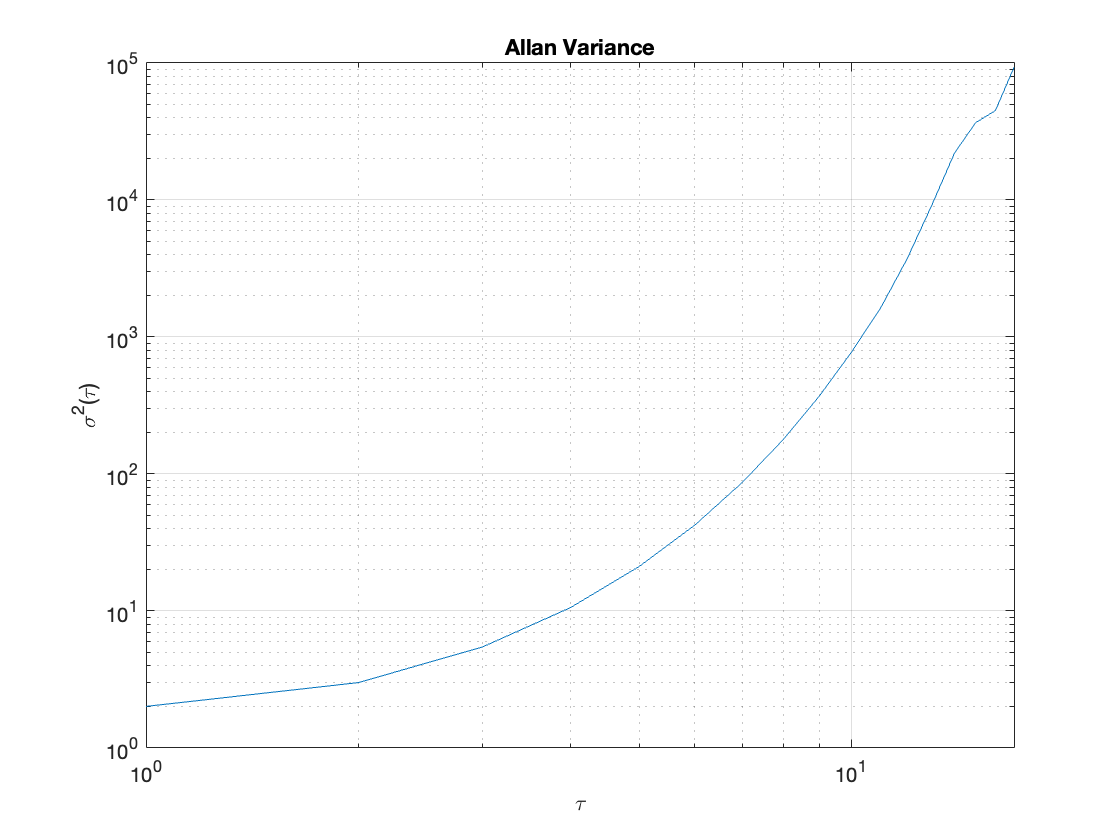


figure
loglog(allanvar(noise_rw1))
xlabel('\tau')
ylabel('\sigma^2(\tau)')
title('Allan Variance')
grid on

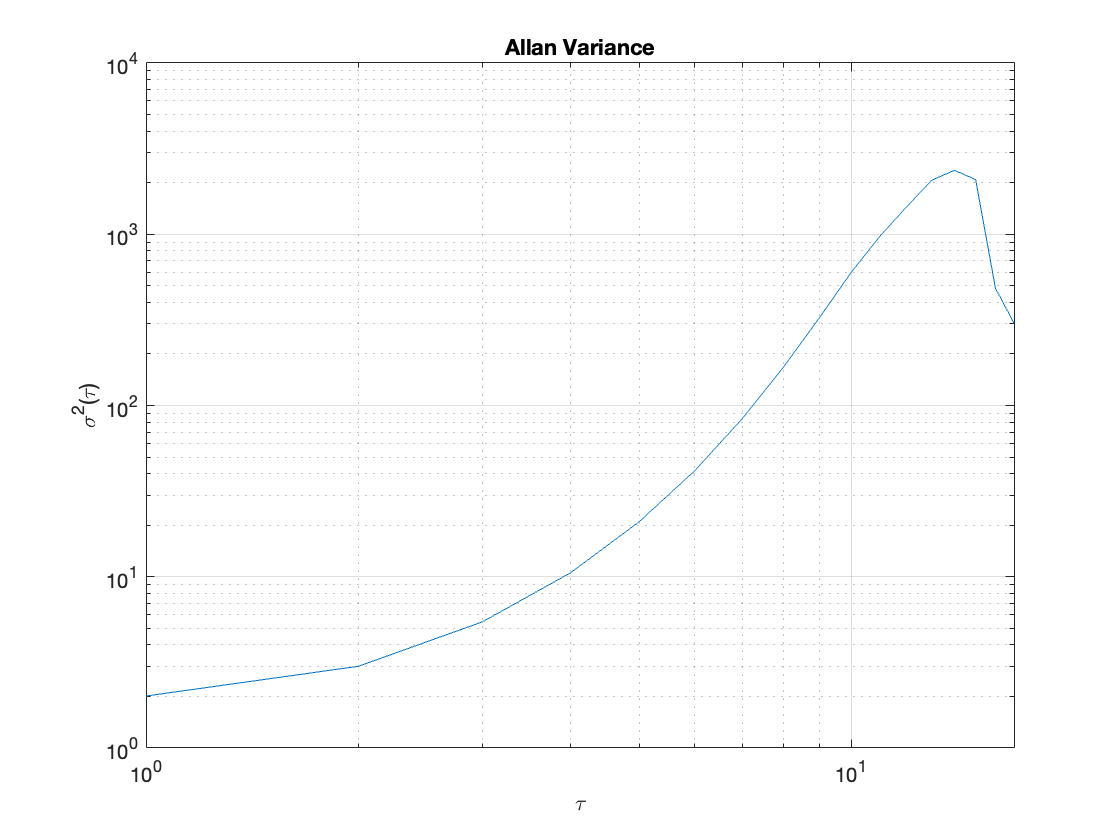


figure
loglog(allanvar(noise_gm11))
xlabel('\tau')
ylabel('\sigma^2(\tau)')
title('Allan Variance')
grid on

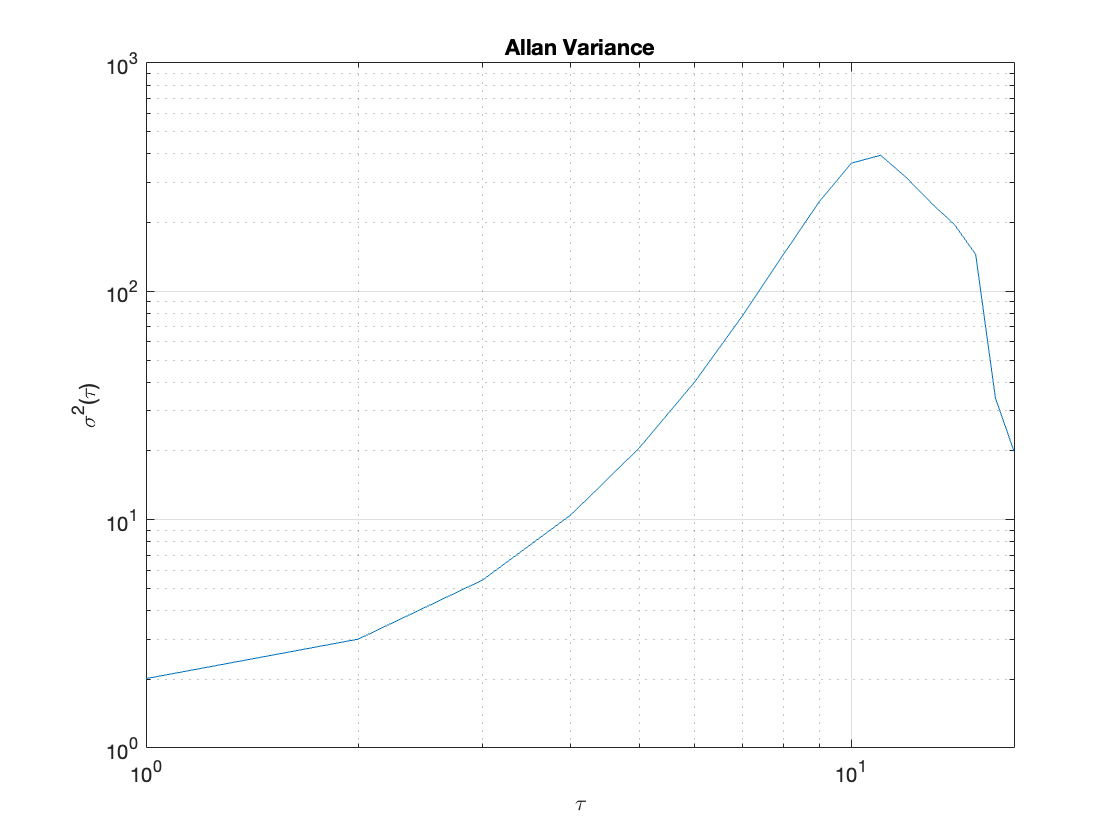


figure
loglog(allanvar(noise_gm21))
xlabel('\tau')
ylabel('\sigma^2(\tau)')
title('Allan Variance')
grid on